## The Order of Finite Differencing

In addition to whether the computation is done on the CPU or GPU, what order of finite differencing is also selectable with the getEnergyTensor function call. The default is 4th order.

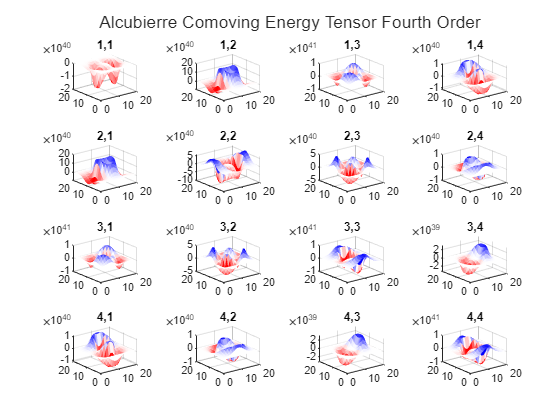

%% Alcubierre
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

% Compute energy tensor on CPU using fourth order
EnergyTensorFourth = getEnergyTensor(Metric,0,'fourth');

% Compute energy tensor on CPU using second order
EnergyTensorSecond = getEnergyTensor(Metric,0,'second');

% Plotting Energy Tensor
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(EnergyTensorFourth.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name + " Energy Tensor Fourth Order")

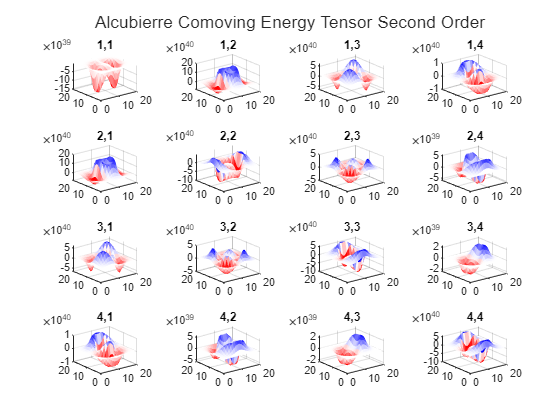


% Plotting Energy Tensor
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(EnergyTensorSecond.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name + " Energy Tensor Second Order")

### Deciding between fourth vs. second order

For almost all applications, fourth order is preferred over second order. However, when analyzing sharp metric transitions, second order can be a helpful check on the finite differencing errors.